read .wav file

resample (re sampling frequency)

generate signal: 

- type (rect, tone, tone-complex, noise)

- sampling frequency

- duration

- periodicity (rect)

- frequency/ies (tone, tone-complex)

plot: time signals

fs1= 20000

fs1 = 20000

T=4

T = 4

frequencies= [100, 200, 300, 400]

frequencies =    100   200   300   400


t1 = 0:1/fs1:T

t1 =          0    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0011    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0024


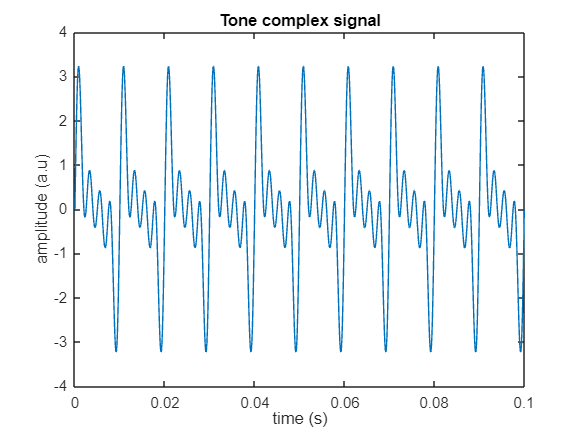


%generate a tone complex
y_generate= sin(2*pi*frequencies(1)*t1)+ sin(2*pi*frequencies(2)*t1)+sin(2*pi*frequencies(3)*t1) +sin(2*pi*frequencies(4)*t1);

%play the sound
%sound(generate_signal, fs);

figure;
plot(t1, generate_signal);
title('Tone complex signal')
xlabel('time (s)');
ylabel('amplitude (a.u)')
xmin=0;
xmax=0.1;
xlim([xmin xmax]) 


fs2=10000

fs2 = 10000

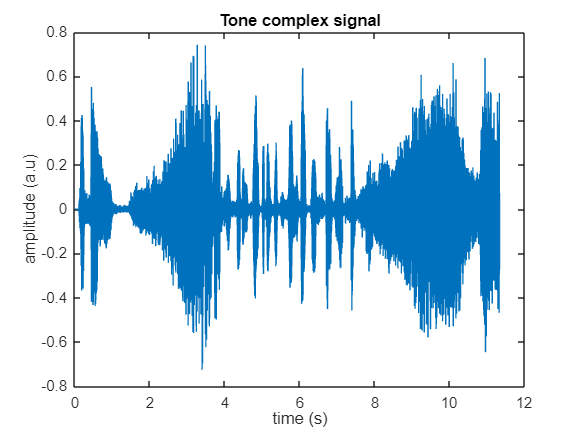

fname = 'mini-me_short.wav';                                 % a file name stored in a string variable
[y_signal, fs_y_signal] = audioread([fname]);

y_signal = resample(y_signal, fs2, fs_y_signal);

t2 = (0:length(y_signal)-1) / fs2;

%play the sound
%sound(y_signal, fs_y_signal);

figure;
plot(t2, y_signal);
title('Tone complex signal')
xlabel('time (s)');
ylabel('amplitude (a.u)')